Millikan Oil drop experiment

clear;
clc;
format long

% Constantes
g = 9.81; % m/s^2
rho_ac = 886; % kg/m^3
eta_aire = 17e-6; % Pa*s
d = 0.0076; % metros
ajuste_eta = 8.2 * 10^-3; % Pa*m
A = 1; %m^2
P_atm = 101325; % Pa
cte_vacio = 8.85e-12;


for i = 1:200

    r(i) = randi([4, 10]) * (10^-7); % Radio de las partículas
    m(i) = rho_ac * 4 / 3 * pi * r(i)^3; % Masa
    p(i) = m(i) * g; % Peso
    eta_eff(i) = eta_aire / (1 + ajuste_eta / (P_atm * r(i))); % Viscosidad efectiva
    st_c(i) = 6 * pi * r(i) * eta_eff(i); % Constante de Stokes

    % Inicialización
    v(i, 1) = 0; % Velocidad inicial
    dt = 1e-6; % Diferencial de tiempo ajustado
    t(i, 1)=0;
    z(i, 1) = 0.006000; % Posición inicial
    j = 1;

    % Iteración para calcular velocidad terminal
    t(i, 2) = dt;
    v(i, 2) = v(i, 1) + dt * (-g - st_c(i) * v(i, 1) / m(i));
    z(i, 2) = z(i, 1) + dt * v(i, 1);

    while abs(v(i, j+1) - v(i, j)) > 1e-12 
       
        j = j + 1;
        t(i, j+1) = t(i, j)+dt;
        v(i, j+1) = v(i, j) + dt * (-g - st_c(i) * v(i, j) / m(i)); % Aceleración revisada
        z(i, j+1) = z(i, j) + dt * v(i, j); % Actualización de la posición
   
    end

  

    v_terminal(i) = v(i, find(v(i,:), 1, "last")); % Velocidad terminal
    z_final(i) = z(i, find(z(i,:), 1, "last")); % Posición final
end

figure;
hold on;
indices = round(linspace(20,200, 5)); % Asegurar índices enteros

for h = indices
    i=max(t(h,:))
    i = find(t(h,:)==i,1,"last")
    subplot(2,1,1);
    plot(t(h,[1,i]), z(h,[1,i]), 'DisplayName', sprintf('Partícula %d', h));
    hold on;

    subplot(2,1,2);
    plot(t(h,[1,i]), v(h,[1,i]), 'DisplayName', sprintf('Partícula %d', h));
    hold on;
end

i =      1.249999999999998e-04


i =    126


i =      2.900000000000001e-05


i =     30


i =      1.249999999999998e-04


i =    126


i =      1.249999999999998e-04


i =    126


i =      1.949999999999996e-04


i =    196


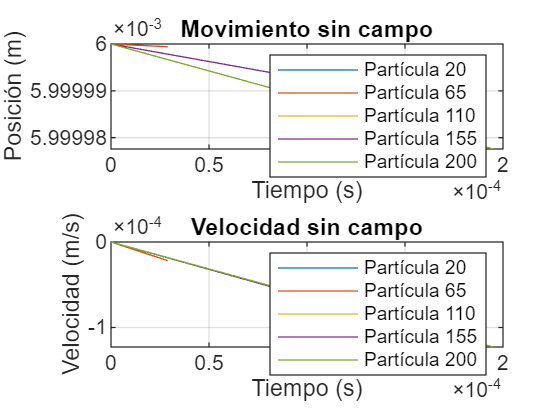



subplot(2,1,1);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Movimiento sin campo');
legend show;
grid on;

subplot(2,1,2);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Velocidad sin campo');
legend show;
grid on;

hold off;

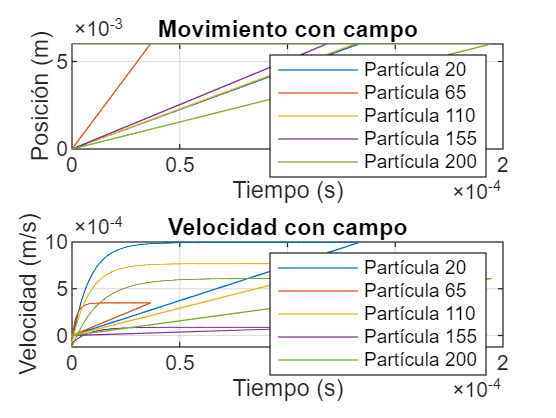

% Segundo cálculo (con fuerza de Coulomb)


V = 500; % Voltaje



for k = 1:200
    q(k) = randi([2, 40]) * 10^-19; % Carga de las partículas
    c(k) = q(k) * V / d; % Fuerza de Coulomb
    

    % Inicialización
    v_2(k, 1) = v_terminal(k); % Velocidad inicial
    dt = 1e-7; % Diferencial de tiempo
    z_2(k, 1) = z_final(k); % Posición inicial
    l = 1;
    t_2(k,1)=0;

    

    % Iteración para calcular velocidad terminal
    t_2(k,2) = t_2(k,1) + dt;
    v_2(k,2) = v_2(k,1) + dt * (-g - v_2(k,1) * st_c(k) / m(k) + c(k) / m(k));
    z_2(k,2) = z_2(k,1) + dt * v_2(k,2);


    while abs(v_2(k, l + 1) - v_2(k, l)) > 1e-12
       
        l = l + 1;
        t_2(k, l+1) = t_2(k, l)+dt;
        v_2(k, l+1) = v_2(k, l) + dt * (-g - v_2(k, l) * st_c(k) / m(k) + c(k) / m(k));
        z_2(k, l+1) = z_2(k, l) + dt * v_2(k, l);
         
    end



    v_terminal_2(k) = v_2(k,find(v_2(k,:), 1, "last"));
    z_final_2(k) = z_2(k,find(z_2(k,:),1, "last"));
end

figure;
hold on;
indices = round(linspace(20,200, 5)); % Asegurar índices enteros

for h = indices
    subplot(2,1,1);
    plot(t_2(h,:), z_2(h,:), 'DisplayName', sprintf('Partícula %d', h));
    hold on;
    
    subplot(2,1,2);
    plot(t_2(h,:), v_2(h,:), 'DisplayName', sprintf('Partícula %d', h));
    hold on;
end

subplot(2,1,1);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Movimiento con campo');
legend show;
grid on;

subplot(2,1,2);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Velocidad con campo');
legend show;
grid on;

hold off;



v_terminal

v_terminal = 1.0e-03 *

  -0.080070311178135  -0.021856522823919  -0.100304580973692  -0.021856522823919  -0.021856522823919  -0.080070311178135  -0.046418758170200  -0.080070311178135  -0.100304580973692  -0.080070311178135  -0.100304580973692  -0.033001475838374  -0.100304580973692  -0.122811180189030  -0.122811180189030  -0.021856522823919  -0.046418758170200  -0.046418758170200  -0.080070311178135  -0.080070311178135  -0.100304580973692  -0.046418758170200  -0.033001475838374  -0.021856522823919  -0.100304580973692  -0.033001475838374  -0.046418758170200  -0.062108369952075  -0.033001475838374  -0.080070311178135  -0.062108369952075  -0.033001475838374  -0.100304580973692  -0.021856522823919  -0.046418758170200  -0.033001475838374  -0.062108369952075  -0.021856522823919  -0.046418758170200  -0.021856522823919  -0.021856522823919  -0.100304580973692  -0.046418758170200  -0.080070311178135  -0.122811180189030  -0.062108369952075  -0.080070311178135  -0.100304580973692  -0.06210836995

v_terminal_2

v_terminal_2 =    0.000654680307174   0.000903816129071   0.000894226349472   0.000595258571275   0.001644354266638   0.000626420664839   0.000613748167631   0.000117747099839  -0.000050578138275   0.000428603167878   0.000123464793609   0.001398229392580   0.000297507724990   0.000631728105377   0.000542958762411   0.001459219732596   0.000264248003764   0.001468081899948   0.000259045312684   0.000993796017561   0.000148328069874   0.000574914816010   0.000205536973417   0.001582642754937   0.000123464793609   0.000110121579862   0.001118581736077   0.000428700406227   0.001255106301862   0.000372083882410   0.000788626890479   0.000062413883544   0.000819636521440   0.002014623336403   0.001157415087996   0.001541352482655   0.000461420995701   0.001582642754937   0.000885581627735   0.001335796709442   0.000718681594358   0.000173191345172   0.000691414870356   0.000202526027448   0.000609535769209   0.001246715143794   0.000004708529517   0.000446687381513   0.000101494510965   0.

r

r = 1.0e-06 *

   0.800000000000000   0.400000000000000   0.900000000000000   0.400000000000000   0.400000000000000   0.800000000000000   0.600000000000000   0.800000000000000   0.900000000000000   0.800000000000000   0.900000000000000   0.500000000000000   0.900000000000000   1.000000000000000   1.000000000000000   0.400000000000000   0.600000000000000   0.600000000000000   0.800000000000000   0.800000000000000   0.900000000000000   0.600000000000000   0.500000000000000   0.400000000000000   0.900000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.500000000000000   0.800000000000000   0.700000000000000   0.500000000000000   0.900000000000000   0.400000000000000   0.600000000000000   0.500000000000000   0.700000000000000   0.400000000000000   0.600000000000000   0.400000000000000   0.400000000000000   0.900000000000000   0.600000000000000   0.800000000000000   1.000000000000000   0.700000000000000   0.800000000000000   0.900000000000000   0.700000000000000   0.

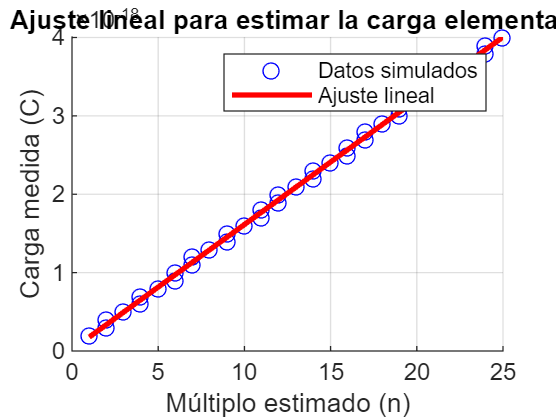

E = V / d; % Campo eléctrico

for k = 1:200
    q_medida(k) = (m(k)*g + st_c(k)*v_terminal_2(k)) / E;
end


% Carga elemental teórica
e_teorico = 1.602e-19;

% Estimar múltiplos enteros de la carga elemental
n_estimado = q_medida / e_teorico;
n_redondeado = round(n_estimado); % Múltiplos enteros más cercanos

% Filtrar posibles outliers (evitar divisiones por cero o valores negativos)
valido = n_redondeado > 0 & isfinite(n_redondeado);

q_valido = q_medida(valido);
n_valido = n_redondeado(valido);

% Ajuste lineal: q = n * e --> pendiente = e
coef = polyfit(n_valido, q_valido, 1);
q_estimada = polyval(coef, n_valido);
e_estimado = coef(1); % Pendiente = carga elemental estimada

figure;
scatter(n_valido, q_valido, 'b', 'o'); % Puntos originales
hold on;
plot(n_valido, q_estimada, 'r', 'LineWidth', 2); % Línea ajustada
xlabel('Múltiplo estimado (n)');
ylabel('Carga medida (C)');
title('Ajuste lineal para estimar la carga elemental');
legend('Datos simulados', 'Ajuste lineal');
grid on;
hold off;


ECM = mean((e_teorico - e_estimado).^(2));
e_porcentual = abs(e_estimado - e_teorico)/e_teorico*100;

% Mostrar resultados
fprintf('Carga elemental estimada: %.4e C\n', e_estimado);

Carga elemental estimada: 1.5952e-19 C


fprintf('Carga elemental teórica : %.4e C\n', e_teorico);

Carga elemental teórica : 1.6020e-19 C


fprintf('Error Calculado por minimos cuadrados: %d',ECM);

Error Calculado por minimos cuadrados: 4.561154e-43

fprintf('Error porcentual: %% %.2f', e_porcentual)

Error porcentual: % 0.42

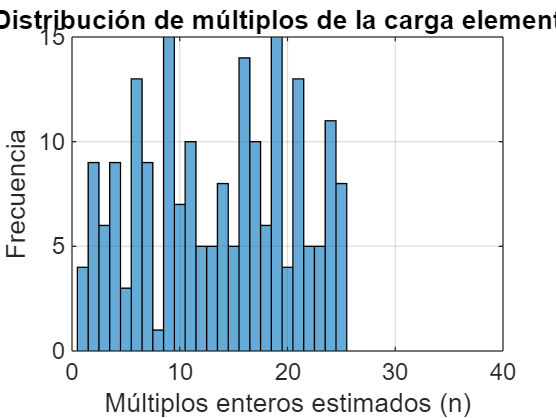

% Histograma de los múltiplos
figure;
histogram(n_valido, 'BinMethod', 'integers');
xlabel('Múltiplos enteros estimados (n)');
ylabel('Frecuencia');
xlim([0,40]);
title('Distribución de múltiplos de la carga elemental');
grid on;

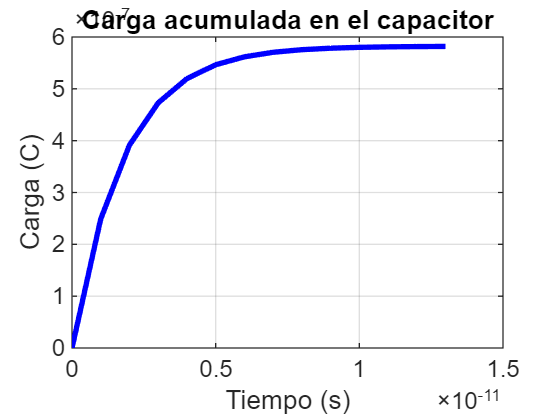


%Circuito RC


C = A * cte_vacio / d; % Capacitancia
R = 2.5 * 1.68e-8 / (pi * (2.58e-3)^2); % Resistencia

tau = R * C; % Constante de tiempo
I = V / R; % Corriente inicial
Q_max = C*V;
% Inicialización
dt = 1e-12; % Paso de tiempo
t_3(1) = 0;

q_capacitor(1) = 0; % Carga inicial en el capacitor
v_capacitor(1) = q_capacitor(1) / C; % Voltaje inicial
E_capacitor(1) = v_capacitor(1) / d; % Intensidad del campo eléctrico

n = 1;

% Iteración temporal

while q_capacitor < 0.999*Q_max
    t_3(n+1) = t_3(n) + dt;
    q_capacitor(n+1) = q_capacitor(n) + dt * (V*C - q_capacitor(n))/(R*C); % Carga acumulada en el capacitor
    v_capacitor(n+1) = q_capacitor(n+1) / C; % Voltaje del capacitor
    E_capacitor(n+1) = v_capacitor(n+1) / d; % Intensidad del campo eléctrico
    n = n+1;
end




% Gráfica de carga en el capacitor

plot(t_3, q_capacitor, 'b', 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Carga (C)');
title('Carga acumulada en el capacitor');
grid on;

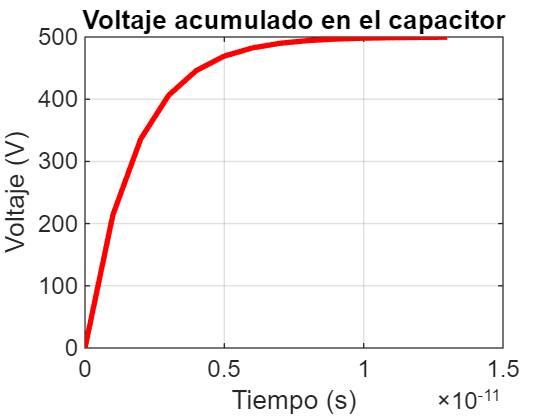


% Gráfica de voltaje en el capacitor

plot(t_3, v_capacitor, 'r', 'LineWidth', 2)
xlabel('Tiempo (s)');
ylabel('Voltaje (V)');
title('Voltaje acumulado en el capacitor');
grid on;

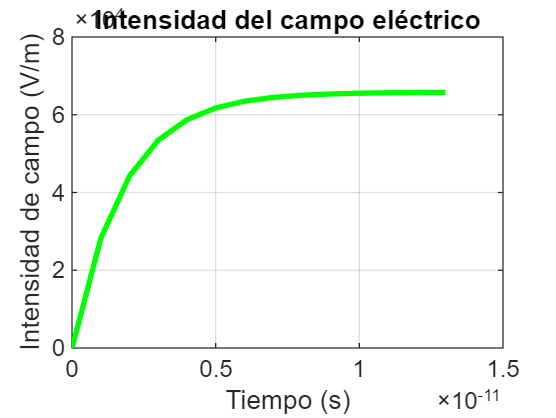


% Gráfica de intensidad del campo eléctrico

plot(t_3, E_capacitor, 'g', 'LineWidth', 2)
xlabel('Tiempo (s)');
ylabel('Intensidad de campo (V/m)');
title('Intensidad del campo eléctrico');
grid on;


z_carga = linspace(z_2(1,1),z_2(1, find(z_2(1,:),1,"last")), n)

z_carga =    0.005999990644753   0.005999996730310   0.006000002815866   0.006000008901422   0.006000014986979   0.006000021072535   0.006000027158092   0.006000033243648   0.006000039329205   0.006000045414761   0.006000051500318   0.006000057585874   0.006000063671431   0.006000069756987


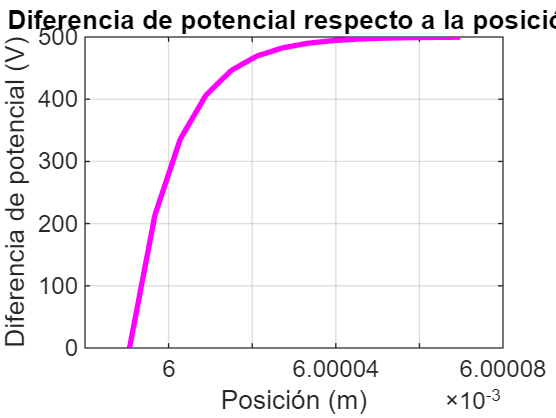


plot(z_carga, v_capacitor, 'm', 'LineWidth', 2)
xlabel('Posición (m)');
ylabel('Diferencia de potencial (V)');
title('Diferencia de potencial respecto a la posición');
grid on;

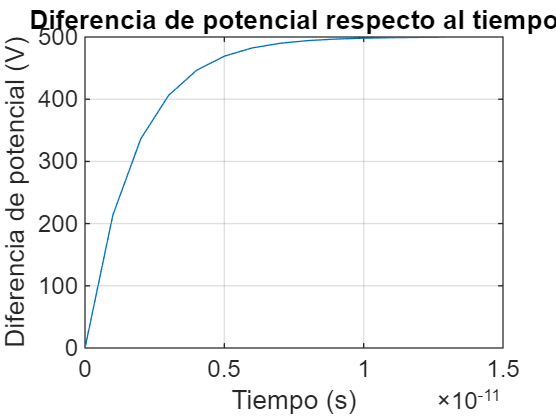


plot(t_3, v_capacitor)
xlabel('Tiempo (s)');
ylabel('Diferencia de potencial (V)');
title('Diferencia de potencial respecto al tiempo');
grid on;


[T, X] = meshgrid(t_3, z_carga); % Matriz para posición y tiempo

V_C = V*T./X

V_C = 1.0e-05 *

                   0   0.008333346326752   0.016666692653504   0.025000038980256   0.033333385307008   0.041666731633760   0.050000077960512   0.058333424287264   0.066666770614016   0.075000116940768   0.083333463267520   0.091666809594272   0.100000155921024   0.108333502247776
                   0   0.008333337874572   0.016666675749145   0.025000013623717   0.033333351498290   0.041666689372862   0.050000027247435   0.058333365122007   0.066666702996580   0.075000040871152   0.083333378745725   0.091666716620297   0.100000054494870   0.108333392369442
                   0   0.008333329422410   0.016666658844820   0.024999988267230   0.033333317689640   0.041666647112051   0.049999976534461   0.058333305956871   0.066666635379281   0.074999964801691   0.083333294224101   0.091666623646511   0.099999953068921   0.108333282491332
                   0   0.008333320970265   0.016666641940530   0.024999962910795   0.033333283881060   0.041666604851324   0.049999925821589

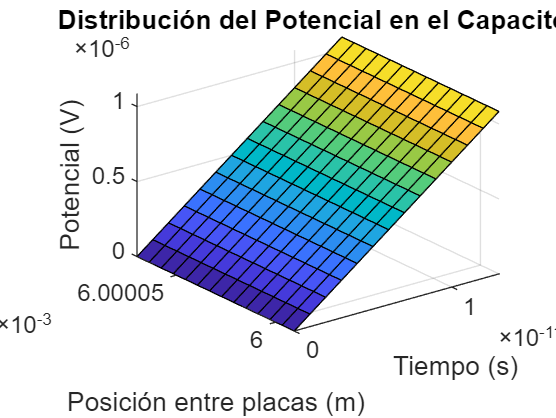



figure;
surf(T, X, V_C);
xlabel('Tiempo (s)');
ylabel('Posición entre placas (m)');
zlabel('Potencial (V)');
title('Distribución del Potencial en el Capacitor');